# Codigos de Proyecto 

- Sección: 2

- N° de grupo: 2

- Titulo del Proyecto Análisis comparativo de la eficiencia de métodos iterativos para el factor de fricción de Colebrook-White en redes de tuberías

- Integrante 1 (líder): Diestro Palao Mateo  (100%)     

- Integrante 2: Urbina Mendoza Adrian Aron Fabricio Alberto (100%)

- Integrante 3: Mitma Martínez Jeanpierre Anthony (100%)

- Integrante 4: Espinoza Camargo Lázaro Andrei (100%)

- Integrante 5: Quevedo Vega Ivonne Gianela (100%)

**Observación:** 

- No olvidar añadir el porcentaje de participación.

- Incluir comentarios relevantes para entender el codigo, tener en cuenta que comentarios de IA anularan la entrega

- El codgio debe de tener una identacion adecuada para facilitar su lectura

- El codigo debe der replicable en cualquier computadora (Uso adecuado de semillas para funciones)

- Las funciones principales deben de ir en la parte inferior de este archivo

- Titulos de los codigos deben reflejar su funcionalidad

## Codigo 1: Parametros base y ecuacion de Colebrook-White

Conjuntos base de la Tabla 1 (Praks y Brkic, 2018), punto inicial x0 = 7.273626085 y tolerancia 1e-8 comunes a los tres métodos.

% CONJUNTOS BASE DE PARAMETROS HIDRAULICOS (TABLA 1)
Re = [3.78e6; 6.23e4; 1.18e7; 5.74e7; 8.31e3];
epsi = [0.00854; 0.012; 0.032; 0.0008; 0.024];
n = length(Re);

% Punto inicial y tolerancia comunes
x0 = 7.273626085;
Tol = 1e-8;

% Intervalo reportado por Praks y Brkic (no contiene la raiz en los extremos del dominio)
a_lit = 3.68;
b_lit = 12.47;

% Intervalo inicial de biseccion ampliado (raices extremas: x = 3.606 y x = 12.975)
a0 = 3.6;
b0 = 13.0;

% Ecuacion de Colebrook-White como F(x) = 0, con x = 1/sqrt(lambda)
Fcol = @(x, Re, e) x + 2*log10(2.51*x/Re + e/3.71);

% Derivada analitica de F (9.3121 = 2.51*3.71)
dFcol = @(x, Re, e) 1 + (2/log(10))*9.3121/(9.3121*x + Re*e);

## Codigo 2: Metodo de la Biseccion

% METODO DE BISECCION: ECUACION DE COLEBROOK
x_bis = zeros(n,1);
it_bis = zeros(n,1);

for j = 1:n

    f = @(x) Fcol(x, Re(j), epsi(j));

    % Verificacion de Bolzano en el intervalo inicial
    if f(a0)*f(b0) < 0
        bolzano = 'cumple';
    else
        bolzano = 'no cumple';
    end

    [raiz,iter] = biseccion(f,a0,b0,Tol);

    x_bis(j) = raiz;
    it_bis(j) = iter;
    lambda = 1/raiz^2;

    fprintf('\n========================================\n');
    fprintf('Punto %d\n',j);
    fprintf('Reynolds = %.4e\n',Re(j));
    fprintf('Rugosidad relativa = %.6f\n',epsi(j));
    fprintf('Bolzano en [%.2f, %.2f]: %s\n',a0,b0,bolzano);
    fprintf('Raiz x = %.10f\n',raiz);
    fprintf('lambda = %.10f\n',lambda);
    fprintf('Iteraciones = %d\n',iter);

end

Punto 1


Reynolds = 3.7800e+06


Rugosidad relativa = 0.008540


Bolzano en [3.60, 13.00]: cumple


Raiz x = 5.2745115044


lambda = 0.0359447537


Iteraciones = 29


Punto 2


Reynolds = 6.2300e+04


Rugosidad relativa = 0.012000


Bolzano en [3.60, 13.00]: cumple


Raiz x = 4.9286344985


lambda = 0.0411667683


Iteraciones = 29


Punto 3


Reynolds = 1.1800e+07


Rugosidad relativa = 0.032000


Bolzano en [3.60, 13.00]: cumple


Raiz x = 4.1283594420


lambda = 0.0586739051


Iteraciones = 29


Punto 4


Reynolds = 5.7400e+07


Rugosidad relativa = 0.000800


Bolzano en [3.60, 13.00]: cumple


Raiz x = 7.3312774731


lambda = 0.0186054717


Iteraciones = 29


Punto 5


Reynolds = 8.3100e+03


Rugosidad relativa = 0.024000


Bolzano en [3.60, 13.00]: cumple


Raiz x = 4.2220410237


lambda = 0.0560989977


Iteraciones = 29


## Codigo 3: Metodo de Newton-Raphson

Se seleccionó x_0=7.273626085 (Praks y Brkic 2018) tras realizar pruebas en el dominio de la ecuación de Colebrook. Se eligio este punto porque pertenece a una zona que requiere, en general, más iteraciones para alcanzar la precisión deseada. Además, mantener el mismo punto inicial permite comparar los resultados de distintos métodos bajo condiciones equivalentes.

% METODO DE NEWTON-RAPHSON: ECUACION DE COLEBROOK
x_new = zeros(n,1);
it_new = zeros(n,1);

for j = 1:n

    f = @(x) Fcol(x, Re(j), epsi(j));
    z = newton(f,x0,Tol);

    fprintf("\n========================================\n");
    fprintf("Punto %d\n",j);
    fprintf("Reynolds=%.4e\n",Re(j));
    fprintf("Rugosidad relativa=%.6f\n",epsi(j));
    fprintf("========================================\n");

    fprintf("Iter     x_i           f(x_i)        f'(x_i)       Error rel.\n");

    for k = 1:size(z,1)
        fprintf('%3d   %.10f   % .3e   %.10f   % .3e\n',z(k,1),z(k,2),z(k,3),z(k,4),z(k,5));
    end

    raiz = z(end,2);
    x_new(j) = raiz;
    it_new(j) = z(end,1);
    lambda = 1/raiz^2;

    fprintf("\nRaiz x = %.10f\n",raiz);
    fprintf("lambda = %.10f\n",lambda);
    fprintf("Iteraciones = %d\n",z(end,1));

end

Punto 1


Reynolds=3.7800e+06


Rugosidad relativa=0.008540


Iter     x_i           f(x_i)        f'(x_i)       Error rel.


  0   7.2736260850    2.000e+00   1.0002500357    1.000e+00
  1   5.2745113552   -1.439e-07   1.0002501796    3.790e-01
  2   5.2745114990    0.000e+00   1.0002501796    2.727e-08
  3   5.2745114990    0.000e+00   1.0002501796    0.000e+00



Raiz x = 5.2745114990


lambda = 0.0359447538


Iteraciones = 3


Punto 2


Reynolds=6.2300e+04


Rugosidad relativa=0.012000


Iter     x_i           f(x_i)        f'(x_i)       Error rel.


  0   7.2736260850    2.369e+00   1.0099203515    1.000e+00
  1   4.9283204122   -3.173e-04   1.0101933945    4.759e-01
  2   4.9286344975   -5.901e-12   1.0101933569    6.373e-05
  3   4.9286344975    0.000e+00   1.0101933569    1.185e-12



Raiz x = 4.9286344975


lambda = 0.0411667683


Iteraciones = 3


Punto 3


Reynolds=1.1800e+07


Rugosidad relativa=0.032000


Iter     x_i           f(x_i)        f'(x_i)       Error rel.


  0   7.2736260850    3.145e+00   1.0000214167    1.000e+00
  1   4.1283594329   -2.612e-09   1.0000214183    7.619e-01
  2   4.1283594355    0.000e+00   1.0000214183    6.327e-10



Raiz x = 4.1283594355


lambda = 0.0586739053


Iteraciones = 2


Punto 4


Reynolds=5.7400e+07


Rugosidad relativa=0.000800


Iter     x_i           f(x_i)        f'(x_i)       Error rel.


  0   7.2736260850   -5.766e-02   1.0001758814    1.000e+00
  1   7.3312774668   -5.918e-11   1.0001758794    7.864e-03
  2   7.3312774669   -8.882e-16   1.0001758794    8.071e-12



Raiz x = 7.3312774669


lambda = 0.0186054718


Iteraciones = 2


Punto 5


Reynolds=8.3100e+03


Rugosidad relativa=0.024000


Iter     x_i           f(x_i)        f'(x_i)       Error rel.


  0   7.2736260850    3.149e+00   1.0302739998    1.000e+00
  1   4.2169047795   -5.310e-03   1.0338839888    7.249e-01
  2   4.2220410129   -1.743e-08   1.0338772009    1.217e-03
  3   4.2220410298    0.000e+00   1.0338772009    3.994e-09



Raiz x = 4.2220410298


lambda = 0.0560989976


Iteraciones = 3


## Codigo 4: Metodo hibrido Newton-Secante

Se escogió un punto semilla de 7.273626085 y una tolerancia de 10^-8. El segundo punto se obtiene como x_{-1} = x_0(1-0.01).

% METODO NEWTON-SECANTE: ECUACION DE COLEBROOK
x_ns = zeros(n,1);
it_ns = zeros(n,1);
resultados = zeros(n,5);

for j = 1:n

    [x, iteraciones, err] = new_sec(Fcol, dFcol, x0, Re(j), epsi(j), Tol);

    x_ns(j) = x;
    it_ns(j) = iteraciones;
    resultados(j,:) = [Re(j), epsi(j), x, iteraciones, err];

end

tabla_ns = array2table(resultados, ...
    'VariableNames', {'Re', 'Rugosidad', 'Raiz', 'Iteraciones', 'Error_final'});

fprintf('\nRESULTADOS DE LAS CINCO EJECUCIONES\n');


RESULTADOS DE LAS CINCO EJECUCIONES


disp(tabla_ns);

       Re       Rugosidad     Raiz     Iteraciones    Error_final
    ________    _________    ______    ___________    ___________

    3.78e+06     0.00854     5.2745         3         1.0103e-15 
       62300       0.012     4.9286         3          4.278e-09 
    1.18e+07       0.032     4.1284         2          6.254e-10 
    5.74e+07      0.0008     7.3313         2         1.3163e-11 
        8310       0.024      4.222         4          1.762e-12 



## Codigo 5: Comparacion de los metodos en el conjunto base

% Se comparan los 3 métodos considerando el residuo, las iteraciones y el tiempo de ejecución

res_bis = zeros(n,1);
res_new = zeros(n,1);
res_ns = zeros(n,1);

% Tiempo usado por cada método numérico
nRepBase = 1e4;
t_bis = zeros(n,1);
t_new = zeros(n,1);
t_ns = zeros(n,1);

% Se realizaron llamadas previas para evitar medir el tiempo de compilacion
biseccion(@(x) Fcol(x, Re(1), epsi(1)),a0,b0,Tol);
newton_analitica(Fcol,dFcol,x0,Re(1),epsi(1),Tol);
new_sec(Fcol,dFcol,x0,Re(1),epsi(1),Tol);

for j = 1:n

    f = @(x) Fcol(x, Re(j), epsi(j));
    res_bis(j) = abs(f(x_bis(j)));
    res_new(j) = abs(f(x_new(j)));
    res_ns(j) = abs(f(x_ns(j)));

    tic;
    for r = 1:nRepBase
        biseccion(f,a0,b0,Tol);
    end
    t_bis(j) = toc/nRepBase;

    % Newton se mide con la derivada analitica
    tic;
    for r = 1:nRepBase
        newton_analitica(Fcol,dFcol,x0,Re(j),epsi(j),Tol);
    end
    t_new(j) = toc/nRepBase;

    tic;
    for r = 1:nRepBase
        new_sec(Fcol,dFcol,x0,Re(j),epsi(j),Tol);
    end
    t_ns(j) = toc/nRepBase;

end

lambda_ref = 1./x_new.^2;

tabla_base = table((1:n)', Re, epsi, lambda_ref, it_bis, it_new, it_ns, ...
    1e6*t_bis, 1e6*t_new, 1e6*t_ns, ...
    'VariableNames', {'Conjunto', 'Re', 'Rugosidad', 'lambda', ...
    'It_Biseccion', 'It_Newton', 'It_NewtonSecante', ...
    't_Biseccion_us', 't_Newton_us', 't_NewtonSecante_us'});
disp(tabla_base);

    Conjunto       Re       Rugosidad     lambda     It_Biseccion    It_Newton    It_NewtonSecante    t_Biseccion_us    t_Newton_us    t_NewtonSecante_us
    ________    ________    _________    ________    ____________    _________    ________________    ______________    ___________    __________________

       1        3.78e+06     0.00854     0.035945         29             3               3                17.077           1.1076           0.85875      
       2           62300       0.012     0.041167         29             3               3                17.116           0.5383           0.67716      
       3        1.18e+07       0.032     0.058674         29             2               2                15.258          0.32971           0.44427      
       4        5.74e+07      0.0008     0.018605         29             2               2                14.702          0.33188           0.46012      
       5            8310       0.024     0.056099         29             3 


fprintf('Diferencia maxima |x_bis - x_new| = %.3e\n', max(abs(x_bis - x_new)));

Diferencia maxima |x_bis - x_new| = 6.521e-09


fprintf('Diferencia maxima |x_ns - x_new|  = %.3e\n', max(abs(x_ns - x_new)));

Diferencia maxima |x_ns - x_new|  = 8.882e-16


fprintf('Residuo maximo |F(x)|: biseccion %.3e, Newton %.3e, Newton-Secante %.3e\n', ...
    max(res_bis), max(res_new), max(res_ns));

Residuo maximo |F(x)|: biseccion 6.521e-09, Newton 8.882e-16, Newton-Secante 0.000e+00


## Codigo 6: Robustez ante la variacion de Re y rugosidad relativa

% Parámetros del dominio de la ecuación de Colebrook-White
nRe = 30;
nE = 26;
Re_m = logspace(log10(4000), 8, nRe);
e_m = linspace(0, 0.05, nE);

IT_bis = NaN(nE,nRe);
bolzano_lit = false(nE,nRe);
IT_new = NaN(nE,nRe);
IT_ns = NaN(nE,nRe);
X_m = NaN(nE,nRe);

% Se evaluan 780 combinaciones de Reynolds y rugosidad para comparar el comportamiento de los 3 métodos

for p = 1:nE
    for q = 1:nRe

        f = @(x) Fcol(x, Re_m(q), e_m(p));

        % Se verifica si el intervalo de Praks y Brkic cumple Bolzano
        bolzano_lit(p,q) = f(a_lit)*f(b_lit) < 0;

        % Biseccion se ejecuta solo si el intervalo cumple Bolzano
        if f(a0)*f(b0) < 0
            [~, IT_bis(p,q)] = biseccion(f,a0,b0,Tol);
        end

        z = newton(f,x0,Tol);
        IT_new(p,q) = z(end,1);
        X_m(p,q) = z(end,2);

        [~, IT_ns(p,q)] = new_sec(Fcol, dFcol, x0, Re_m(q), e_m(p), Tol);

    end
end

nTot = nE*nRe;
metodo = {'Biseccion'; 'Newton-Raphson'; 'Newton-Secante'};
it_min = [min(IT_bis(:)); min(IT_new(:)); min(IT_ns(:))];
it_max = [max(IT_bis(:)); max(IT_new(:)); max(IT_ns(:))];
it_med = [mean(IT_bis(:),'omitnan'); mean(IT_new(:)); mean(IT_ns(:))];
fallos = [sum(isnan(IT_bis(:))); sum(isnan(IT_new(:))); sum(isnan(IT_ns(:)))];

tabla_robustez = table(metodo, it_min, it_max, it_med, fallos, ...
    'VariableNames', {'Metodo', 'It_min', 'It_max', 'It_media', 'Puntos_no_evaluados'});
fprintf('Puntos evaluados: %d\n', nTot);

Puntos evaluados: 780


disp(tabla_robustez);

          Metodo          It_min    It_max    It_media    Puntos_no_evaluados
    __________________    ______    ______    ________    ___________________

    {'Biseccion'     }      29        29           29              0         
    {'Newton-Raphson'}       2         4       2.7897              0         
    {'Newton-Secante'}       2         5       2.9423              0         




% Puntos donde el intervalo de Praks y Brkic no contiene la raiz
[pf, qf] = find(~bolzano_lit);
fprintf('Puntos sin Bolzano en [%.2f, %.2f]: %d\n', a_lit, b_lit, length(pf));

Puntos sin Bolzano en [3.68, 12.47]: 8


for k = 1:length(pf)
    fprintf('Sin Bolzano: Re = %.3e, e = %.3f, raiz x = %.4f\n', Re_m(qf(k)), e_m(pf(k)), X_m(pf(k),qf(k)));
end

Sin Bolzano: Re = 4.000e+03, e = 0.046, raiz x = 3.6654
Sin Bolzano: Re = 4.000e+03, e = 0.048, raiz x = 3.6352
Sin Bolzano: Re = 4.000e+03, e = 0.050, raiz x = 3.6060
Sin Bolzano: Re = 5.672e+03, e = 0.048, raiz x = 3.6735
Sin Bolzano: Re = 5.672e+03, e = 0.050, raiz x = 3.6427
Sin Bolzano: Re = 8.042e+03, e = 0.050, raiz x = 3.6700
Sin Bolzano: Re = 7.053e+07, e = 0.000, raiz x = 12.6904
Sin Bolzano: Re = 1.000e+08, e = 0.000, raiz x = 12.9745


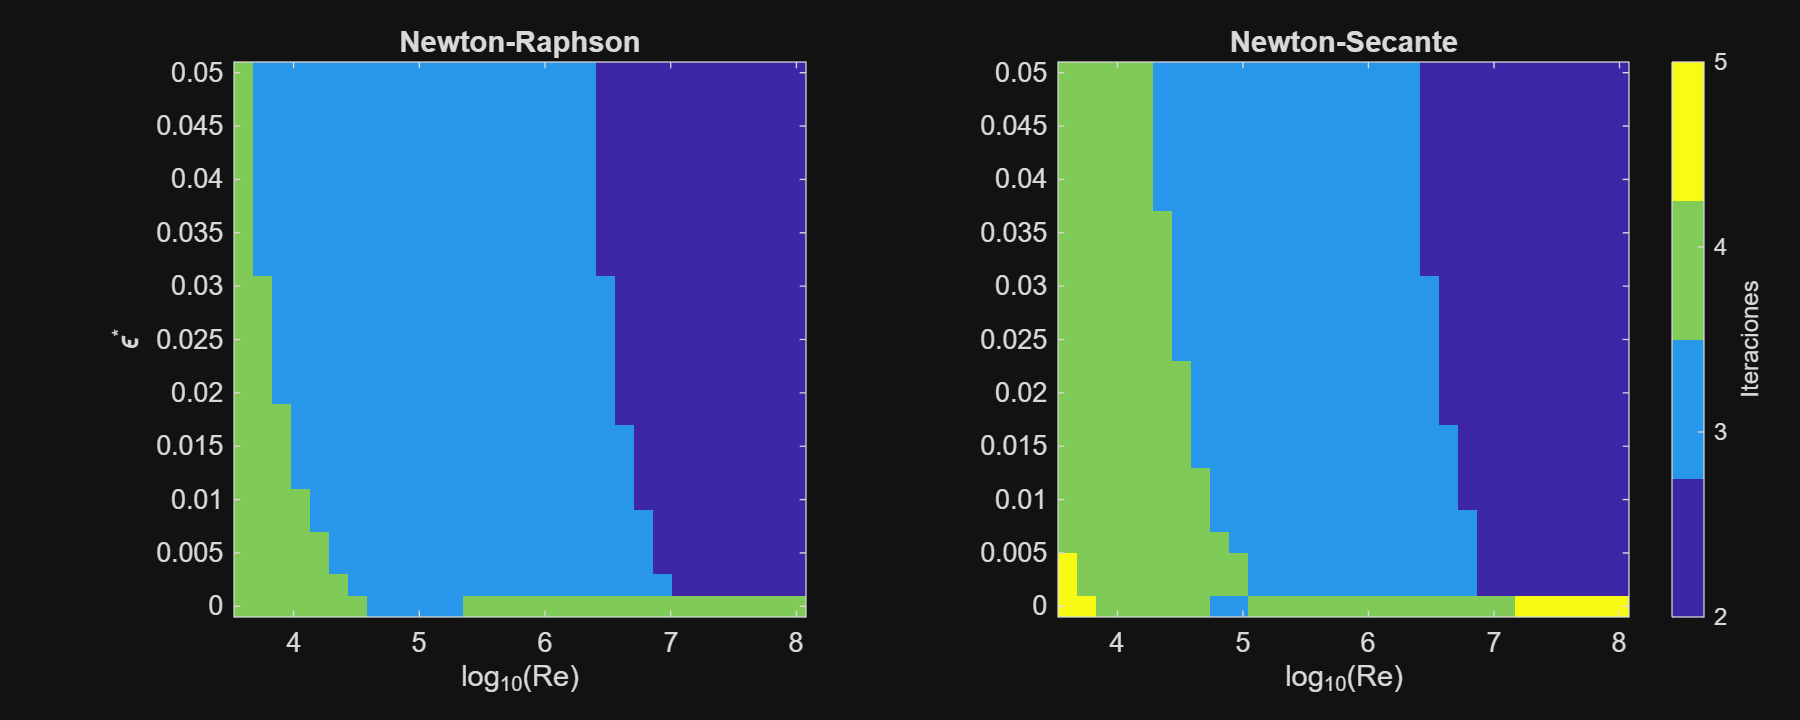


% Mapas de iteraciones de los metodos abiertos
fig_rob = figure('Position', [100 100 900 360]);
tl = tiledlayout(1,2);
lim = [min([IT_new(:); IT_ns(:)]) max([IT_new(:); IT_ns(:)])];

nexttile
imagesc(log10(Re_m), e_m, IT_new);
set(gca,'YDir','normal');
clim(lim);
title('Newton-Raphson');
xlabel('log_{10}(Re)');
ylabel('\epsilon^*');

nexttile
imagesc(log10(Re_m), e_m, IT_ns);
set(gca,'YDir','normal');
clim(lim);
title('Newton-Secante');
xlabel('log_{10}(Re)');

colormap(parula(lim(2)-lim(1)+1));
cb = colorbar;
cb.Layout.Tile = 'east';
cb.Label.String = 'Iteraciones';
cb.Ticks = lim(1):lim(2);

## Codigo 7: Costo computacional de la resolucion repetitiva

Se simula una red con N tuberías cuyos parámetros se generan aleatoriamente en el dominio de Colebrook. Para Newton-Raphson se usa la derivada analítica, porque la función newton deriva simbólicamente en cada llamada y su tiempo no reflejaría el costo del método.

% Se evalua el tiempo necesario para resolver distintas cantidades de tuberías mediante los 3 métodos
% Se utiliza la derivada analítica para medir Newton
rng(2);   % semilla para reproducibilidad

N_val = [1e2 1e3 1e4 1e5];
Nmax = max(N_val);
nRep = 3;

% Re log-uniforme en [4000, 1e8] y rugosidad uniforme en [0, 0.05]
Re_gen = 10.^(log10(4000) + (8 - log10(4000))*rand(2*Nmax,1));
e_gen = 0.05*rand(2*Nmax,1);

% Se conservan solo tuberias donde la biseccion es aplicable
valido = arrayfun(@(r,e) Fcol(a0,r,e)*Fcol(b0,r,e) < 0, Re_gen, e_gen);
Re_red = Re_gen(valido);
e_red = e_gen(valido);
Re_red = Re_red(1:Nmax);
e_red = e_red(1:Nmax);
fprintf('Tuberias generadas fuera del intervalo de biseccion: %.2f %%\n', 100*mean(~valido));

Tuberias generadas fuera del intervalo de biseccion: 0.00 %



% Llamadas previas para evitar medir el tiempo de compilacion
f = @(x) Fcol(x, Re_red(1), e_red(1));
biseccion(f,a0,b0,Tol);
newton_analitica(Fcol,dFcol,x0,Re_red(1),e_red(1),Tol);
new_sec(Fcol,dFcol,x0,Re_red(1),e_red(1),Tol);

T = zeros(length(N_val),3);

for k = 1:length(N_val)
    N = N_val(k);
    t_rep = zeros(nRep,3);

    for r = 1:nRep

        tic;
        for m = 1:N
            f = @(x) Fcol(x, Re_red(m), e_red(m));
            biseccion(f,a0,b0,Tol);
        end
        t_rep(r,1) = toc;

        tic;
        for m = 1:N
            newton_analitica(Fcol,dFcol,x0,Re_red(m),e_red(m),Tol);
        end
        t_rep(r,2) = toc;

        tic;
        for m = 1:N
            new_sec(Fcol,dFcol,x0,Re_red(m),e_red(m),Tol);
        end
        t_rep(r,3) = toc;

    end

    % Se toma el menor tiempo de las repeticiones
    T(k,:) = min(t_rep,[],1);
end

% Iteraciones promedio en la red mas grande
it_red = zeros(Nmax,3);
for m = 1:Nmax
    f = @(x) Fcol(x, Re_red(m), e_red(m));
    [~, it_red(m,1)] = biseccion(f,a0,b0,Tol);
    [~, it_red(m,2)] = newton_analitica(Fcol,dFcol,x0,Re_red(m),e_red(m),Tol);
    [~, it_red(m,3)] = new_sec(Fcol,dFcol,x0,Re_red(m),e_red(m),Tol);
end

tabla_costo = table(metodo, mean(it_red)', 1e6*(T(end,:)/Nmax)', T(end,:)', T(end,1)./T(end,:)', ...
    'VariableNames', {'Metodo', 'It_media', 't_por_tuberia_us', 't_total_N1e5_s', 'Aceleracion_vs_biseccion'});
disp(tabla_costo);

          Metodo          It_media    t_por_tuberia_us    t_total_N1e5_s    Aceleracion_vs_biseccion
    __________________    ________    ________________    ______________    ________________________

    {'Biseccion'     }         29          14.519              1.4519                     1         
    {'Newton-Raphson'}     2.7463         0.38891            0.038891                37.332         
    {'Newton-Secante'}     2.8988         0.49935            0.049935                29.075         



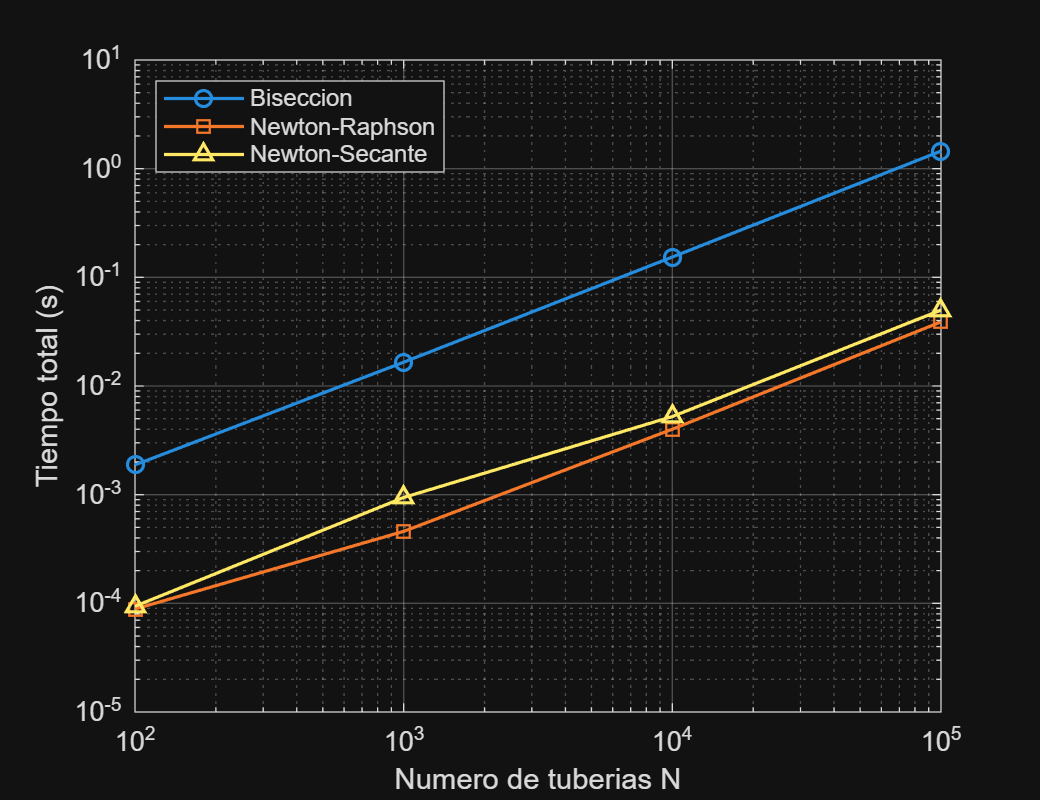


fig_costo = figure('Position', [100 100 520 400]);
loglog(N_val, T(:,1), '-o', N_val, T(:,2), '-s', N_val, T(:,3), '-^', 'LineWidth', 1.2);
grid on;
xlabel('Numero de tuberias N');
ylabel('Tiempo total (s)');
legend(metodo, 'Location', 'northwest');

## Funciones Principales

%FUNCION DE BISECCION
function [x, iter] = biseccion(f, a, b, tol)
      if f(a)*f(b) > 0
           error('La funcion debe tener signos opuestos en a y b');
      end
      iter = 0;
      while (b - a) / 2 > tol
           c = (a + b) / 2;
           if f(c) == 0
                 break;
           end
           if f(a)*f(c) < 0
                 b = c;
           else
                 a = c;
           end
           iter = iter + 1;
      end
      x = (a + b) / 2;
end

%FUNCION DE NEWTON-RAPHSON
function z = newton(f,x0,Tol)
      syms x
      df = diff(f,x);
      df = matlabFunction(df);
      dr = 1;
      i = 0;
      z = [i x0 f(x0) df(x0) dr];
      while(dr > Tol)
           x1 = x0 - f(x0)/df(x0);
           dr = abs(x1 - x0)/abs(x1);
           x0 = x1;
           i = i + 1;
           z = [z; i x1 f(x1) df(x1) dr];
      end
end

%FUNCION DE NEWTON-RAPHSON CON DERIVADA ANALITICA DADA
function [x, iteraciones, err] = newton_analitica(f, df, x_sem, Re_sem, e_sem, tol)

    x = x_sem;
    iteraciones = 0;
    maxit = 1000;
    err = Inf;

    while iteraciones < maxit

        % Paso de Newton con la derivada analitica
        x_nuevo = x - f(x, Re_sem, e_sem)/df(x, Re_sem, e_sem);
        iteraciones = iteraciones + 1;

        % se calcula el error relativo para verificar la convergencia
        err = abs(x_nuevo - x)/abs(x_nuevo);

        x = x_nuevo;

        if err <= tol
            break;
        end
    end

end

%FUNCION DE NEWTON-SECANTE
function [x, iteraciones, err] = new_sec(f, df_fun, x_sem, Re_sem, e_sem, tol)

    x_ant = x_sem*(1-0.01);
    x = x_sem;

    iteraciones = 0;
    maxit = 1000;
    err = Inf;

    % F(x_{i-1}) se calcula una sola vez y luego se reutiliza
    Fx_ant = f(x_ant, Re_sem, e_sem);

    while iteraciones < maxit

        % Evaluamos la función en xi
        Fx = f(x, Re_sem, e_sem);
        dFx = df_fun(x, Re_sem, e_sem);

        dF_sec = (Fx - Fx_ant)/(x - x_ant);

        % Denominador de Newton-Secante
        den = dFx + dF_sec;

        if ~isfinite(den) || den == 0
            error('Denominador nulo o no valido.');
        end

        % Formula iterativa de Newton-Secante
        x_nuevo = x - 2*Fx/den;
        iteraciones = iteraciones + 1;

        % Criterio de convergencia (error relativo, igual que newton)
        err = abs(x_nuevo - x)/abs(x_nuevo);

        x_ant = x;
        Fx_ant = Fx;
        x = x_nuevo;

        if err <= tol
            break;
        end
    end

    if iteraciones == maxit && err > tol
        warning('Se alcanzo el maximo de iteraciones.');
    end
end